clear

addpath("matlab_functions\")

#### Read MFD data

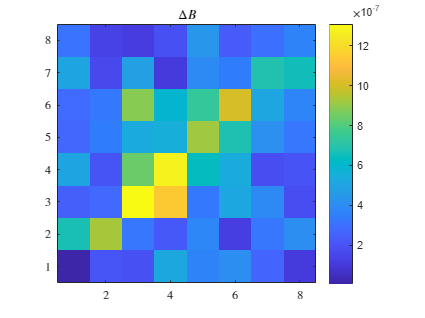

[B0,f,defects] = readMFD('data/B_ec_defectless.txt');
assert(isempty(defects))

[B,f2,defects] = readMFD('data/B_ec_defect_circ2mm.txt');
assert(all(f==f2))

delta_B = B - B0;

idx = [1];
f = f(idx);
delta_B = reshape(delta_B(idx,:).', size(delta_B,2), 1, []);

figure
imagesc(vecnorm(reshape(delta_B,8,8,[]), 2, 3).')
colorbar
title('$\Delta B$')
axis square xy


clear idx f2 B0 B

#### Load $\Phi$

load('data\Phi.mat', 'Phi','freqs','voxels_center')

Phi = Phi(:,:,f == freqs);

xylim = 15e-3;
mask = -xylim < voxels_center(1,:) &  voxels_center(1,:) < xylim & ...
       -xylim < voxels_center(2,:) &  voxels_center(2,:) < xylim & ...
                                      voxels_center(3,:) > -0.6e-3;

Phi = Phi(:, mask, :);
voxels_center = voxels_center(:, mask);

y = delta_B;

Phi = cat(3, real(Phi),imag(Phi));
y   = cat(3, real(y),  imag(y)  );

Phi_ = reshape(pagetranspose(Phi), size(Phi,2), []).';
y_   = reshape(pagetranspose(y),   size(y  ,2), []).';

clear freqs delta_B k xylim mask

#### Tikhonov regularization

lambda = 1e-14;

tic
R = (Phi_' * Phi_ + lambda * eye(size(Phi_,2))) \ Phi_';
z = R * y_;
fprintf("Tikhonov regularization uses %.2f seconds\n", toc)

Tikhonov regularization uses 0.20 seconds


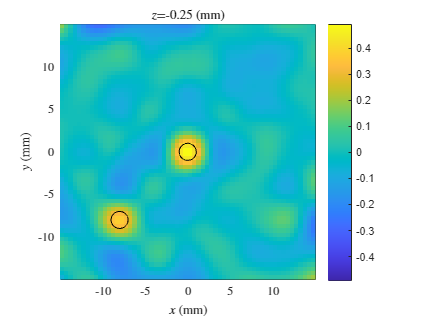


displayReconstruction(z, voxels_center, defects)

clear lambda R 

#### L1 regularization

lambda = 1e-14;
beta = 1e-17;

reg{1}.lambda = lambda;
reg{1}.L = speye(size(Phi,2));

tic
z = L1Regularize(Phi_, y_, reg, beta);
fprintf("L1 regularization uses %.2f seconds", toc)

L1 regularization uses 0.57 seconds

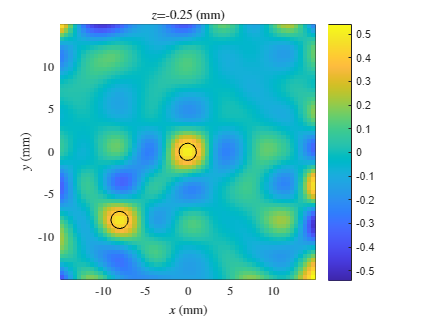


displayReconstruction(z, voxels_center, defects)


clear lambda beta reg

#### Sparse Bayesian learning

tic
z = SBL(Phi_, y_, 'MaxIterations',20);
fprintf("SBL uses %.2f seconds\n", toc)

SBL uses 1.44 seconds


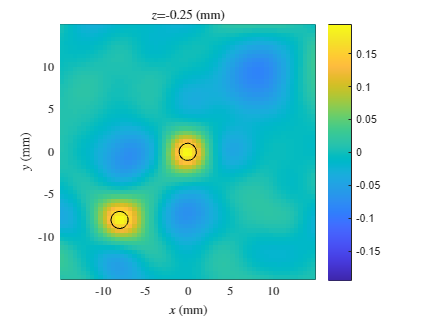


displayReconstruction(z, voxels_center, defects)

#### Bernoulli Bayesian learning

tic
z = BBL(Phi, y, 'Method','WeightedPrior', 'Sparsity',0.49, 'MaxIterations',50);
fprintf("BBL uses %.2f seconds\n", toc)

BBL uses 4.33 seconds


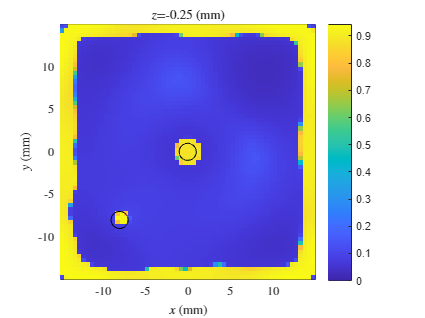


displayReconstruction(z, voxels_center, defects)

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(c, element_centers, defects)

c = real(c);

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;
    dx = (x(2) - x(1)) / size(c_layer,1);
    dy = (y(2) - y(1)) / size(c_layer,2);

    cmax = max(c_layer, [], 'all');
    if any(c < 0), cmin = -cmax; else, cmin = 0; end

    subplot(length(z),1,k)
    hold on
    imagesc(x, y, c_layer.', [cmin cmax])
    colorbar
    axis square xy
    box on
    xlim(x + [-dx dx]/2)
    ylim(y + [-dy dy]/2)
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end